## **Description of the daily puzzle:**

**DragonFjord's A-Puzzle-A-Day**

A-Puzzle-A-Day is a very fun and addictive  puzzle that gives you a new challenge every single day of the year. All  you need to do is fit these eight pieces into the calendar frame to  leave one month and one day showing. Can you find your birthday? Your  favorite holidays? Your anniversary? Today’s date? Every day you have a  new puzzle!

* Test in Matlab R2021b, with Ghostscript 9.54.0 (https://github.com/ArtifexSoftware/ghostpdl-downloads/releases)

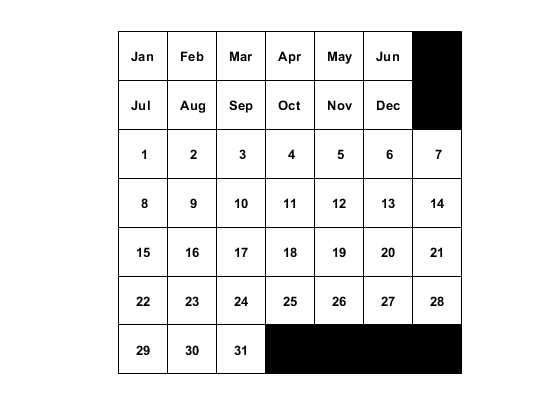

clear

time=clock;
seed=round(sum(time(4:6))*sum(time(2:3))/10);
rng(seed);

%% Frame shape
FrameDefault = false(7,7);
FrameDefault(1:2,7)=true(2,1);FrameDefault(7,4:7)=true(1,4);

Text_Frame = {'Jan','Feb','Mar','Apr','May','Jun',''; 'Jul','Aug','Sep','Oct','Nov','Dec','';
        '1','2','3','4','5','6','7';'8','9','10','11','12','13','14';
        '15','16','17','18','19','20','21';'22','23','24','25','26','27','28';
        '29','30','31','','','',''};

if true
    figure;
    temp_FrameDefault = [flip(~FrameDefault), ones(size(FrameDefault,1),1); ones(1,size(FrameDefault,2)+1)];
    H1 = pcolor(temp_FrameDefault);
    colormap(gray(2));
    set(gca, 'xticklabel', [], 'yticklabel', [])
    axis square
    labelTable(FrameDefault, Text_Frame)
end

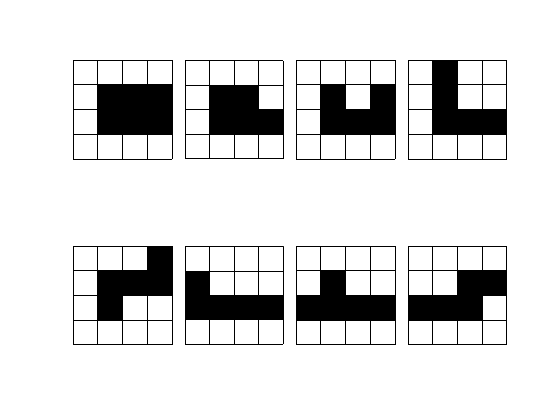


%% Pieces shape
% 8 pieces, start in a 5x5 empty space
NoPuzzlePieces = 8;
PuzzlePieces = repmat({false(5,5)},NoPuzzlePieces,8);
PuzzlePiecesBlockNo = zeros(NoPuzzlePieces,1);

% □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□
% □■■■□ % □■■■□ % □■■■□ % □■■■□ % □■□□□ % ■■■■□ % ■■■■□ % ■■■□□
% □■■■□ % □■■□□ % □■□■□ % □■□□□ % □■■■□ % ■□□□□ % □■□□□ % □□■■□
% □□□□□ % □□□□□ % □□□□□ % □■□□□ % □□□■□ % □□□□□ % □□□□□ % □□□□□
% □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□
PuzzlePieces{1,1}(2:3,2:4)=true;
PuzzlePieces{2,1}(2,2:4)=true;PuzzlePieces{2,1}(3,2:3)=true;
PuzzlePieces{3,1}(2,2:4)=true;PuzzlePieces{3,1}(3,[2,4])=true;
PuzzlePieces{4,1}(2,2:4)=true;PuzzlePieces{4,1}(3:4,2)=true;
PuzzlePieces{5,1}(2,2)=true;PuzzlePieces{5,1}(3,2:4)=true;PuzzlePieces{5,1}(4,4)=true;
PuzzlePieces{6,1}(2,1:4)=true;PuzzlePieces{6,1}(3,1)=true;
PuzzlePieces{7,1}(2,1:4)=true;PuzzlePieces{7,1}(3,2)=true;
PuzzlePieces{8,1}(2,1:3)=true;PuzzlePieces{8,1}(3,3:4)=true;

for n=1:NoPuzzlePieces
    PuzzlePiecesBlockNo(n) = sum(PuzzlePieces{n,1},'all');
end
ListOfPossibleSize = cell(NoPuzzlePieces,1);
for n=1:NoPuzzlePieces
    ListOfPossibleSize{n} = listPossibleSize(PuzzlePiecesBlockNo(n:end));
end

if true
    MaxNperRow = 4;
    NRow = ceil(NoPuzzlePieces/MaxNperRow);
    H2 = tiledlayout(NRow,MaxNperRow,'TileSpacing','compact','Padding','loose');
    for i=1:NoPuzzlePieces
        nexttile
        H20 = pcolor(~PuzzlePieces{i});
        colormap(gray(2));
        set(gca, 'xticklabel', [], 'yticklabel', []);
        axis square
    end
end

## **Choose the Date:**

% Flip Vertical, Flip Horizontal, Roate(counterclockwise) 90
% [Boolean number, Boolean number, Boolean number]
for n=1:NoPuzzlePieces
    for i=0:1:7
        temp = PuzzlePieces{n,1};
        binstr = dec2bin(i,3)=='1';
        if binstr(3)
            temp = flip(temp);
        end
        if binstr(2)
            temp = flip(temp,2);
        end
        if binstr(1)
            temp = rot90(temp);
        end
        PuzzlePieces{n,i+1} = temp;
    end
end

%% Qusetion
Month = 8;
Day = 21;
FrameQuestion = dailyPuzzle(Month,Day);
filename = ['output/Result_', num2str(Month,'%02d'), num2str(Day,'%02d'), '.txt'];
if ~isfolder('output')
    mkdir('output');
end

Frame = FrameDefault | FrameQuestion;

%% Initalization
SizeFrame = size(Frame);
ExpandedFrame = true(SizeFrame(1)+4, SizeFrame(2)+4);
ExpandedFrame(3:SizeFrame(1)+2,3:SizeFrame(2)+2) = Frame;
LN = SizeFrame(1)*SizeFrame(2)*8;

ExpandedPuzzlePieces = repmat({false(SizeFrame(1),SizeFrame(2))},NoPuzzlePieces,LN);
ExpandedPuzzlePiecesFlag = false(NoPuzzlePieces,LN);
for i=1:NoPuzzlePieces
    for L0=1:LN
        R0 = ceil(L0/8);
        P0 = rem(L0,8);
        if P0==0
            P0 = 8;
        end
        R0x = ceil(R0/SizeFrame(2));
        R0y = rem(R0,SizeFrame(2));
        if R0y==0
            R0y = SizeFrame(2);
        end
        tempFrame = false(SizeFrame(1)+4, SizeFrame(2)+4);
        tempFrame(R0x:R0x+4,R0y:R0y+4) = PuzzlePieces{i,P0};
        OverlayFrame = tempFrame & ExpandedFrame;
        if sum(OverlayFrame,'all')==0
            ExpandedPuzzlePieces{i,L0} = tempFrame(3:SizeFrame(1)+2,3:SizeFrame(2)+2);
            ExpandedPuzzlePiecesFlag(i,L0) = true;
        end
    end
end
for i=1:NoPuzzlePieces
    tempIndex = zeros(1,LN);
    for L0=1:LN
        % treat matrix of [0,1] as binary
        binValue = num2str(reshape(ExpandedPuzzlePieces{i,L0},1,[]));
        tempIndex(1,L0) = bin2dec(binValue);
    end
    [~, UniqueIndex, ~] = unique(tempIndex);
    tempFlag = false(1,LN);
    tempFlag(UniqueIndex) = true;
    ExpandedPuzzlePiecesFlag(i,:) = ExpandedPuzzlePiecesFlag(i,:) & tempFlag;
end

FindAllAnswer = false;
IsOutput = false;
IsMerge = false;

* Install Ghostscript (https://www.ghostscript.com/releases/gsdnld.html) if you want to merge pdf files.

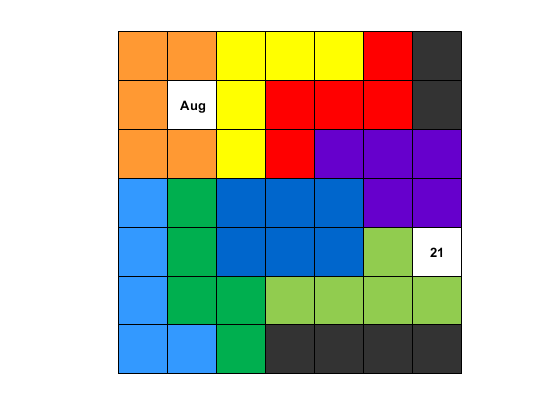

%% Find only one solution
if ~FindAllAnswer

Solution_onlyOne = zeros(1,NoPuzzlePieces);
Flag_endloop = false;
ExpandedPuzzlePieces_temp = ExpandedPuzzlePieces;
ExpandedPuzzlePiecesFlag_temp = ExpandedPuzzlePiecesFlag;
for i=1:NoPuzzlePieces
    newIndx = randperm(LN);
    for j=1:LN
        ExpandedPuzzlePieces{i,j} = ExpandedPuzzlePieces_temp{i,newIndx(j)};
        ExpandedPuzzlePiecesFlag(i,j) = ExpandedPuzzlePiecesFlag_temp(i,newIndx(j));
    end
end
clear ExpandedPuzzlePieces_temp ExpandedPuzzlePiecesFlag_temp
for L1=1:LN
    if Flag_endloop
        break
    end
    if ExpandedPuzzlePiecesFlag(1,L1)
    Frame1 = Frame;
    [isfit1, newFrame1] = isFit(Frame1, ExpandedPuzzlePieces{1,L1}, ListOfPossibleSize{2});
    if isfit1
    Ouptput1 = Solution_onlyOne;
    Ouptput1(1) = L1;
    for L2=1:LN
        if Flag_endloop
            break
        end
        if ExpandedPuzzlePiecesFlag(2,L2)
        Frame2 = newFrame1;
        [isfit2, newFrame2] = isFit(Frame2, ExpandedPuzzlePieces{2,L2}, ListOfPossibleSize{3});
        if isfit2
        Ouptput2 = Ouptput1;
        Ouptput2(2) = L2;
        for L3=1:LN
            if Flag_endloop
                break
            end
            if ExpandedPuzzlePiecesFlag(3,L3)
            Frame3 = newFrame2;
            [isfit3, newFrame3] = isFit(Frame3, ExpandedPuzzlePieces{3,L3}, ListOfPossibleSize{4});
            if isfit3
            Ouptput3 = Ouptput2;
            Ouptput3(3) = L3;
            for L4=1:LN
                if Flag_endloop
                    break
                end
                if ExpandedPuzzlePiecesFlag(4,L4)
                Frame4 = newFrame3;
                [isfit4, newFrame4] = isFit(Frame4, ExpandedPuzzlePieces{4,L4}, ListOfPossibleSize{5});
                if isfit4
                Ouptput4 = Ouptput3;
                Ouptput4(4) = L4;
                for L5=1:LN
                    if Flag_endloop
                        break
                    end
                    if ExpandedPuzzlePiecesFlag(5,L5)
                    Frame5 = newFrame4;
                    [isfit5, newFrame5] = isFit(Frame5, ExpandedPuzzlePieces{5,L5}, ListOfPossibleSize{6});
                    if isfit5
                    Ouptput5 = Ouptput4;
                    Ouptput5(5) = L5;
                    for L6=1:LN
                        if Flag_endloop
                            break
                        end
                        if ExpandedPuzzlePiecesFlag(6,L6)
                        Frame6 = newFrame5;
                        [isfit6, newFrame6] = isFit(Frame6, ExpandedPuzzlePieces{6,L6}, ListOfPossibleSize{7});
                        if isfit6
                        Ouptput6 = Ouptput5;
                        Ouptput6(6) = L6;
                        for L7=1:LN
                            if Flag_endloop
                                break
                            end
                            if ExpandedPuzzlePiecesFlag(7,L7)
                            Frame7 = newFrame6;
                            [isfit7, newFrame7] = isFit(Frame7, ExpandedPuzzlePieces{7,L7}, ListOfPossibleSize{8});
                            if isfit7
                            Ouptput7 = Ouptput6;
                            Ouptput7(7) = L7;
                            for L8=1:LN
                                if ExpandedPuzzlePiecesFlag(8,L8)
                                Frame8 = newFrame7;
                                [isfit8, newFrame8] = isFit(Frame8, ExpandedPuzzlePieces{8,L8}, []);
                                if isfit8
                                    Ouptput8 = Ouptput7;
                                    Ouptput8(8) = L8;
                                    Solution_onlyOne = Ouptput8;
                                    Flag_endloop = true;
                                    break
                                end
                                end
                            end
                            end
                            end
                        end
                        end
                        end
                    end
                    end
                    end
                end
                end
                end
            end
            end
            end
        end
        end
        end
    end
    end
    end
end

else

fprintf(['Solving the puzzle on ', date2String(Month,Day), ', it might take a few minutes.\n']);
Solution_all = [];
for L1=1:LN
    if ExpandedPuzzlePiecesFlag(1,L1)
    Frame1 = Frame;
    [isfit1, newFrame1] = isFit(Frame1, ExpandedPuzzlePieces{1,L1}, ListOfPossibleSize{2});
    if isfit1
    Ouptput1 = zeros(1,NoPuzzlePieces);
    Ouptput1(1) = L1;
    for L2=1:LN
        if ExpandedPuzzlePiecesFlag(2,L2)
        Frame2 = newFrame1;
        [isfit2, newFrame2] = isFit(Frame2, ExpandedPuzzlePieces{2,L2}, ListOfPossibleSize{3});
        if isfit2
        Ouptput2 = Ouptput1;
        Ouptput2(2) = L2;
        for L3=1:LN
            if ExpandedPuzzlePiecesFlag(3,L3)
            Frame3 = newFrame2;
            [isfit3, newFrame3] = isFit(Frame3, ExpandedPuzzlePieces{3,L3}, ListOfPossibleSize{4});
            if isfit3
            Ouptput3 = Ouptput2;
            Ouptput3(3) = L3;
            for L4=1:LN
                if ExpandedPuzzlePiecesFlag(4,L4)
                Frame4 = newFrame3;
                [isfit4, newFrame4] = isFit(Frame4, ExpandedPuzzlePieces{4,L4}, ListOfPossibleSize{5});
                if isfit4
                Ouptput4 = Ouptput3;
                Ouptput4(4) = L4;
                for L5=1:LN
                    if ExpandedPuzzlePiecesFlag(5,L5)
                    Frame5 = newFrame4;
                    [isfit5, newFrame5] = isFit(Frame5, ExpandedPuzzlePieces{5,L5}, ListOfPossibleSize{6});
                    if isfit5
                    Ouptput5 = Ouptput4;
                    Ouptput5(5) = L5;
                    for L6=1:LN
                        if ExpandedPuzzlePiecesFlag(6,L6)
                        Frame6 = newFrame5;
                        [isfit6, newFrame6] = isFit(Frame6, ExpandedPuzzlePieces{6,L6}, ListOfPossibleSize{7});
                        if isfit6
                        Ouptput6 = Ouptput5;
                        Ouptput6(6) = L6;
                        for L7=1:LN
                            if ExpandedPuzzlePiecesFlag(7,L7)
                            Frame7 = newFrame6;
                            [isfit7, newFrame7] = isFit(Frame7, ExpandedPuzzlePieces{7,L7}, ListOfPossibleSize{8});
                            if isfit7
                            Ouptput7 = Ouptput6;
                            Ouptput7(7) = L7;
                            for L8=1:LN
                                if ExpandedPuzzlePiecesFlag(8,L8)
                                Frame8 = newFrame7;
                                [isfit8, newFrame8] = isFit(Frame8, ExpandedPuzzlePieces{8,L8}, []);
                                if isfit8
                                    Ouptput8 = Ouptput7;
                                    Ouptput8(8) = L8;
                                    Solution_all = [Solution_all; Ouptput8];
                                end
                                end
                            end
                            end
                            end
                        end
                        end
                        end
                    end
                    end
                    end
                end
                end
                end
            end
            end
            end
        end
        end
        end
    end
    end
    end
    if rem(L1,SizeFrame(1)*SizeFrame(2))==0
        fprintf('|||');
    end
end
fprintf(' \n');

end
%% Output

ColorMaps = [1 1 1; 0 0.4 0.8; 0.4 0 0.8; 1 0.6 0.2; 1 1 0; 1 0 0; 0.2 0.6 1; 0.57 0.8 0.31; 0 0.69 0.31; 0.2 0.2 0.2];
NRow = 4;
NColumn = 7;
NImage = NRow*NColumn;
if ~FindAllAnswer
    if Solution_onlyOne(1)>0
        HeatMapMatrix = zeros(SizeFrame(1), SizeFrame(2));
        for n=1:NoPuzzlePieces
            HeatMapMatrix = HeatMapMatrix + n.*ExpandedPuzzlePieces{n,Solution_onlyOne(n)};
        end
        HeatMapMatrix = HeatMapMatrix + (NoPuzzlePieces+1).*FrameDefault;
        temp_HeatMapMatrix = [flip(HeatMapMatrix), zeros(size(HeatMapMatrix,1),1); zeros(1,size(HeatMapMatrix,2)+1)];
        figure;
        H0 = pcolor(temp_HeatMapMatrix);
        colormap(ColorMaps);
        set(gca, 'xticklabel', [], 'yticklabel', [])
        axis square
        labelTable(HeatMapMatrix, Text_Frame)
        if IsOutput
            titlename = ['Solution of ', date2String(Month,Day), ' (randomly chosen)'];
            title(titlename);
%             set(gcf,'Position',[120 100 1520 820]);
%             orient(gcf,'landscape')
            PrintFileName = ['output/Solution_', num2str(Month,'%02d'), num2str(Day,'%02d'), '_RandomChosen.pdf'];
            print(gcf,PrintFileName,'-dpdf','-bestfit'); %PDF
%             close all
        end
    else
        fprintf('No solution was found for Daily Puzzle on %s.\n', date2String(Month,Day));
    end
else
    ImageNumber = size(Solution_all,1);
    if ImageNumber>0
    fprintf('Daily Puzzle on %s solved, %d solution(s) found.\n\n', date2String(Month,Day), ImageNumber);
    fprintf('Exporting pdf files, don''t close the windows showing up...........');
    HeatMapMatrix = cell(ImageNumber,1);
    for i=1:ImageNumber
        HeatMapMatrix{i} = zeros(SizeFrame(1), SizeFrame(2));
        for n=1:NoPuzzlePieces
            HeatMapMatrix{i} = HeatMapMatrix{i} + n.*ExpandedPuzzlePieces{n,Solution_all(i,n)};
        end
        HeatMapMatrix{i} = HeatMapMatrix{i} + (NoPuzzlePieces+1).*FrameDefault;
    end

    NPage = ceil(ImageNumber/NImage);
    PrintFileName = cell(NPage,1);
    for p=1:NPage
        H0 = tiledlayout(NRow,NColumn,'TileSpacing','compact','Padding','loose');
        for i=1:min(NImage,ImageNumber-(p-1)*NImage)
            n = (p-1)*NImage+i;
            nexttile
            H = heatmap(HeatMapMatrix{n},'Colormap',ColorMaps,'CellLabelColor','none');
            H.Position = [0.13,0.11,0.775,0.815];
            H.ColorbarVisible = 'off';
            H.XDisplayLabels = nan(size(H.XDisplayData));
            H.YDisplayLabels = nan(size(H.YDisplayData));
        end
        titlename = ['Solution of ', date2String(Month,Day), ' (Page', num2str(p,'%02d'), ')'];
        title(H0, titlename);
        set(gcf,'Position',[120 100 1520 820]);
        %H0.Visible = 'off';
        orient(gcf,'landscape')
        if p==1 && IsMerge
            PrintFileName{p,1} = ['output/Solution_', num2str(Month,'%02d'), num2str(Day,'%02d'), '.pdf'];
        else
            PrintFileName{p,1} = ['output/Solution_', num2str(Month,'%02d'), num2str(Day,'%02d'), '_P', num2str(p,'%02d'), '.pdf'];
        end
        print(gcf,PrintFileName{p,1},'-dpdf','-bestfit'); %PDF
        close all
    end

    if NPage>1 && IsMerge
        append_pdfs_edit(PrintFileName');
        for i=2:NPage
            delete(PrintFileName{i,1});
        end
    end
    fprintf('   Done!\n');

    end
end


 
%% Function

function [frame_question] = dailyPuzzle(Month,Day)
    frame_question = false(7,7);
    remMonth = rem(Month,6);
    if remMonth==0
        remMonth = 6;
    end
    frame_question(ceil(Month/6),remMonth) = true;
    remDay = rem(Day,7);
    if remDay==0
        remDay = 7;
    end
    frame_question(ceil(Day/7)+2,remDay) = true;
end

function [] = labelTable(Frame, TextFrame)
    row = size(Frame,1);
    column = size(Frame,2);
    for i=1:row
        for j=1:column
            if Frame(i,j)==0
                shiftx = 0.25+0.1*(3-length(TextFrame{i,j}));
                text(j+shiftx, row+1.5-i, TextFrame{i,j}, 'FontWeight', 'bold');
            end
        end
    end
end

function [StringDate] = date2String(Month, Day)
    switch Month
        case 1
            StringDate1 = 'Jan';
        case 2
            StringDate1 = 'Feb';
        case 3
            StringDate1 = 'Mar';
        case 4
            StringDate1 = 'Apr';
        case 5
            StringDate1 = 'May';
        case 6
            StringDate1 = 'Jun';
        case 7
            StringDate1 = 'Jul';
        case 8
            StringDate1 = 'Aug';
        case 9
            StringDate1 = 'Sep';
        case 10
            StringDate1 = 'Oct';
        case 11
            StringDate1 = 'Nov';
        case 12
            StringDate1 = 'Dec';
    end
    switch Day
        case 1
            StringDate2 = '01st';
        case 2
            StringDate2 = '02nd';
        case 3
            StringDate2 = '03rd';
        case 21
            StringDate2 = '21st';
        case 22
            StringDate2 = '22nd';
        case 23
            StringDate2 = '23rd';
        case 31
            StringDate2 = '31st';
        otherwise
            StringDate2 = [num2str(Day,'%02d'), 'th'];
    end
    StringDate = [StringDate1, '-', StringDate2];
end

function [isfit, newFrame] = isFit(Frame, PuzzlePieces, ListOfPossibleSize)
    newFrame = Frame & PuzzlePieces;
    if sum(newFrame,'all')==0
        newFrame = Frame | PuzzlePieces;
        input = bwlabel(~newFrame,4);%input = bwconncomp(~newFrame,4);
        props = regionprops(input, 'Area', 'PixelIdxList');
        ListOfSize = [props.Area]';
        ListOfSize = unique([ListOfSize;ListOfPossibleSize]);
        if length(ListOfSize)~=length(ListOfPossibleSize)
            isfit = false;
        else
            isfit = true;
        end
    else
        isfit = false;
    end
end

function [ListOfPossibleSize] = listPossibleSize(PuzzlePiecesBlockNo)
    NoPuzzlePieces = length(PuzzlePiecesBlockNo);
    List = zeros(2^NoPuzzlePieces,1);
    for i=0:length(List)-1
        binstr = dec2bin(i,NoPuzzlePieces)=='1';
        List(i+1) = sum(PuzzlePiecesBlockNo(binstr));
    end
    List = unique(List);
    ListOfPossibleSize = List(2:end,1);
end

%APPEND_PDFS Appends/concatenates multiple PDF files
%
% Example:
%   append_pdfs(output, input1, input2, ...)
%   append_pdfs(output, input_list{:})
%   append_pdfs test.pdf temp1.pdf temp2.pdf
%
% This function appends multiple PDF files to an existing PDF file, or
% concatenates them into a PDF file if the output file doesn't yet exist.
%
% This function requires that you have ghostscript installed on your
% system. Ghostscript can be downloaded from: http://www.ghostscript.com
%
% IN:
%    output - string of output file name (including the extension, .pdf).
%             If it exists it is appended to; if not, it is created.
%    input1 - string of an input file name (including the extension, .pdf).
%             All input files are appended in order.
%    input_list - cell array list of input file name strings. All input
%                 files are appended in order.

% Copyright: Oliver Woodford, 2011

% Thanks to Reinhard Knoll for pointing out that appending multiple pdfs in
% one go is much faster than appending them one at a time.

% Thanks to Michael Teo for reporting the issue of a too long command line.
% Issue resolved on 5/5/2011, by passing gs a command file.

% Thanks to Martin Wittmann for pointing out the quality issue when
% appending multiple bitmaps.
% Issue resolved (to best of my ability) 1/6/2011, using the prepress
% setting

% modified
function append_pdfs_edit(varargin)
% Are we appending or creating a new file
varargin = varargin{1};
append = exist(varargin{1}, 'file') == 2;
if append
    output = [tempname '.pdf'];
else
    output = varargin{1};
    varargin = varargin(2:end);
end
% Create the command file
cmdfile = [tempname '.txt'];
fh = fopen(cmdfile, 'w');
fprintf(fh, '-q -dNOPAUSE -dBATCH -sDEVICE=pdfwrite -dPDFSETTINGS=/prepress -sOutputFile="%s" -f', output);
fprintf(fh, ' "%s"', varargin{:});
fclose(fh);
% Call ghostscript
ghostscript(['@"' cmdfile '"']);
% Delete the command file
delete(cmdfile);
% Rename the file if needed
if append
    movefile(output, varargin{1});
end
end

function varargout = ghostscript(cmd)
%GHOSTSCRIPT  Calls a local GhostScript executable with the input command
%
% Example:
%   [status result] = ghostscript(cmd)
%
% Attempts to locate a ghostscript executable, finally asking the user to
% specify the directory ghostcript was installed into. The resulting path
% is stored for future reference.
% 
% Once found, the executable is called with the input command string.
%
% This function requires that you have Ghostscript installed on your
% system. You can download this from: http://www.ghostscript.com
%
% IN:
%   cmd - Command string to be passed into ghostscript.
%
% OUT:
%   status - 0 iff command ran without problem.
%   result - Output from ghostscript.

% Copyright: Oliver Woodford, 2009-2010

% Thanks to Jonas Dorn for the fix for the title of the uigetdir window on
% Mac OS.

% Thanks to Nathan Childress for the fix to the default location on 64-bit
% Windows systems.

% 27/4/11 - Find 64-bit Ghostscript on Windows. Thanks to Paul Durack and
% Shaun Kline for pointing out the issue

% 4/5/11 - Thanks to David Chorlian for pointing out an alternative
% location for gs on linux.

% Call ghostscript
[varargout{1:nargout}] = system(sprintf('"%s" %s', gs_path, cmd));
return
end

function path = gs_path
% Return a valid path
% Start with the currently set path
path = user_string('ghostscript');
% Check the path works
if check_gs_path(path)
    return
end
% Check whether the binary is on the path
if ispc
    bin = {'gswin32c.exe', 'gswin64c.exe'};
else
    bin = {'gs'};
end
for a = 1:numel(bin)
    path = bin{a};
    if check_store_gs_path(path)
        return
    end
end
% Search the obvious places
if ispc
    default_location = 'C:\Program Files\gs\';
    dir_list = dir(default_location);
    if isempty(dir_list)
        default_location = 'C:\Program Files (x86)\gs\'; % Possible location on 64-bit systems 
        dir_list = dir(default_location);
    end
    executable = {'\bin\gswin32c.exe', '\bin\gswin64c.exe'};
    ver_num = 0;
    % If there are multiple versions, use the newest
    for a = 1:numel(dir_list)
        ver_num2 = sscanf(dir_list(a).name, 'gs%g');
        if ~isempty(ver_num2) && ver_num2 > ver_num
            for b = 1:numel(executable)
                path2 = [default_location dir_list(a).name executable{b}];
                if exist(path2, 'file') == 2
                    path = path2;
                    ver_num = ver_num2;
                end
            end
        end
    end
    if check_store_gs_path(path)
        return
    end
else
    bin = {'/usr/bin/gs', '/usr/local/bin/gs'};
    for a = 1:numel(bin)
        path = bin{a};
        if check_store_gs_path(path)
            return
        end
    end
end
% Ask the user to enter the path
while 1
    if strncmp(computer, 'MAC', 3) % Is a Mac
        % Give separate warning as the uigetdir dialogue box doesn't have a
        % title
        uiwait(warndlg('Ghostscript not found. Please locate the program.'))
    end
    base = uigetdir('/', 'Ghostcript not found. Please locate the program.');
    if isequal(base, 0)
        % User hit cancel or closed window
        break;
    end
    base = [base filesep];
    bin_dir = {'', ['bin' filesep], ['lib' filesep]};
    for a = 1:numel(bin_dir)
        for b = 1:numel(bin)
            path = [base bin_dir{a} bin{b}];
            if exist(path, 'file') == 2
                if check_store_gs_path(path)
                    return
                end
            end
        end
    end
end
error('Ghostscript not found. Have you installed it from www.ghostscript.com?');
end

function good = check_store_gs_path(path)
% Check the path is valid
good = check_gs_path(path);
if ~good
    return
end
% Update the current default path to the path found
if ~user_string('ghostscript', path)
    warning('Path to ghostscript installation could not be saved. Enter it manually in ghostscript.txt.');
    return
end
return
end

function good = check_gs_path(path)
% Check the path is valid
[good message] = system(sprintf('"%s" -h', path));
good = good == 0;
return
end

%USER_STRING  Get/set a user specific string
%
% Examples:
%   string = user_string(string_name)
%   saved = user_string(string_name, new_string)
%
% Function to get and set a string in a system or user specific file. This
% enables, for example, system specific paths to binaries to be saved.
%
% IN:
%   string_name - String containing the name of the string required. The
%                 string is extracted from a file called (string_name).txt,
%                 stored in the same directory as user_string.m.
%   new_string - The new string to be saved under the name given by
%                string_name.
%
% OUT:
%   string - The currently saved string. Default: ''.
%   saved - Boolean indicating whether the save was succesful

% Copyright (C) Oliver Woodford 2011

% This method of saving paths avoids changing .m files which might be in a
% version control system. Instead it saves the user dependent paths in
% separate files with a .txt extension, which need not be checked in to
% the version control system. Thank you to Jonas Dorn for suggesting this
% approach.

function string = user_string(string_name, string)
if ~ischar(string_name)
    error('string_name must be a string.');
end
% Create the full filename
string_name = fullfile(fileparts(mfilename('fullpath')), '.ignore', [string_name '.txt']);
if nargin > 1
    % Set string
    if ~ischar(string)
        error('new_string must be a string.');
    end
    % Make sure the save directory exists
    dname = fileparts(string_name);
    if ~exist(dname, 'dir')
        % Create the directory
        try
            if ~mkdir(dname)                
                string = false;
                return
            end
        catch
            string = false;
            return
        end
        % Make it hidden
        try
            fileattrib(dname, '+h');
        catch
        end
    end
    % Write the file
    fid = fopen(string_name, 'w');
    if fid == -1
        string = false;
        return
    end
    try
        fwrite(fid, string, '*char');
    catch
        fclose(fid);
        string = false;
        return
    end
    fclose(fid);
    string = true;
else
    % Get string
    fid = fopen(string_name, 'r');
    if fid == -1
        string = '';
        return
    end
    string = fread(fid, '*char')';
    fclose(fid);
end
return
end